# Vector Part 2:

## Vector Extention Concept

### Code Exercise (03_01)

> Linear weighted combination.

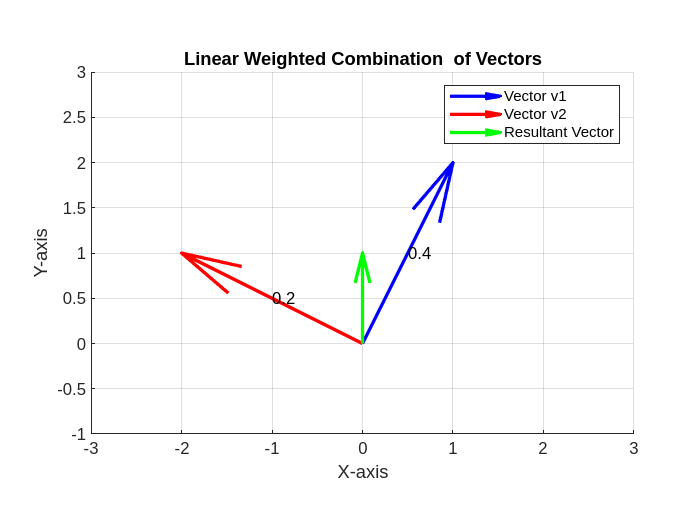

clc; clear; close all;

% Define vectors
v1 = [1; 2]; % example vector 1
v2 = [-2; 1]; % example vector 2

% Define weights
alpha = 0.4;
beta = 0.2;

% Compute the linear weighted combination
resultant_vector = alpha * v1 + beta * v2;

% Visualize vetors
figure;
hold on;

% Plot vectors
quiver(0, 0, v1(1), v1(2), 'Color', 'b', LineWidth=2, MaxHeadSize=1, AutoScale='off', DisplayName='Vector v1');
quiver(0, 0, v2(1), v2(2), 'r', LineWidth=2, MaxHeadSize=1, AutoScale='off', DisplayName='Vector v2');
quiver(0, 0, resultant_vector(1), resultant_vector(2), 'g', LineWidth=2, MaxHeadSize=1, AutoScale='off', DisplayName='Resultant Vector');

% Set axis equal, xlim, and ylim
axis equal;
xlim([-3, 3]);
ylim([-1, 3]);

% Add labels
xlabel('X-axis');
ylabel('Y-axis');

% Add text
text(v1(1)/2, v1(2)/2, num2str(alpha));
text(v2(1)/2, v2(2)/2, num2str(beta));

% Add legend
legend("show");

% Set title
title('Linear Weighted Combination  of Vectors');

% Show grid
grid on;
hold off;

### Code Exercise (03_02)

> Vector Span.

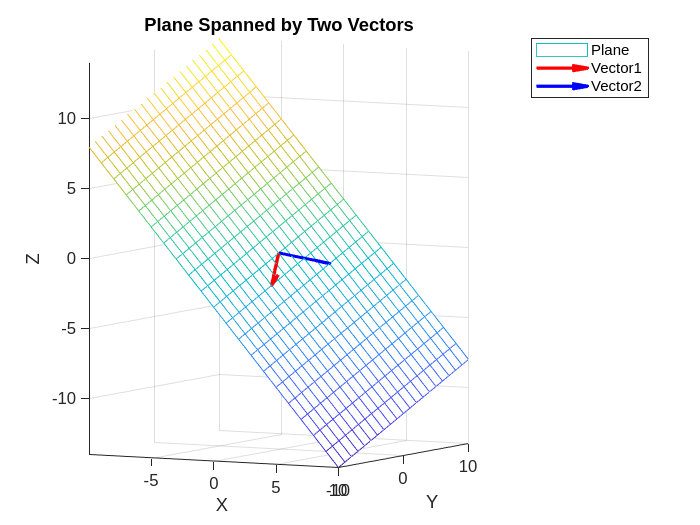

clc; clear; close all;

% Define two 3D vectors
v1 = [1; -3; -2];
v2 = [2; 4; -1];

% Calculate the normal vector (cross product of the two vectors)
normal = cross(v1, v2);

% Choose a point on the plane (for example, using v1)
point = v1;

% Equation of the plane: ax + by + cz + d = 0
% where a, b, c are component of the normal vector, and d is the constant
% term of the plane equation
a = normal(1);
b = normal(2);
c = normal(3);
d = -dot(normal, point);

% Code for visualization
[x, y] = meshgrid(-10:1:10, -10:1:10); % create a grid to represent the plane
z = (-d -a*x -b*y) / c; % Calculate z values of the plane

% Draw the plane
figure;
mesh(x, y, z, DisplayName='Plane');
hold on;

% Draw the two vectors
quiver3(0, 0, 0, v1(1), v1(2), v1(3), 'r', Linewidth=2, AutoScale='off', MaxHeadSize=2, DisplayName='Vector1');
quiver3(0, 0, 0, v2(1), v2(2), v2(3), 'b', 'LineWidth', 2, AutoScale='off', MaxHeadSize=2, DisplayName='Vector2');

xlabel('X'); ylabel('Y'); zlabel('Z');
title('Plane Spanned by Two Vectors');
legend("show");
axis equal;
grid on;

### Code Exercise (03_03)

> Basis

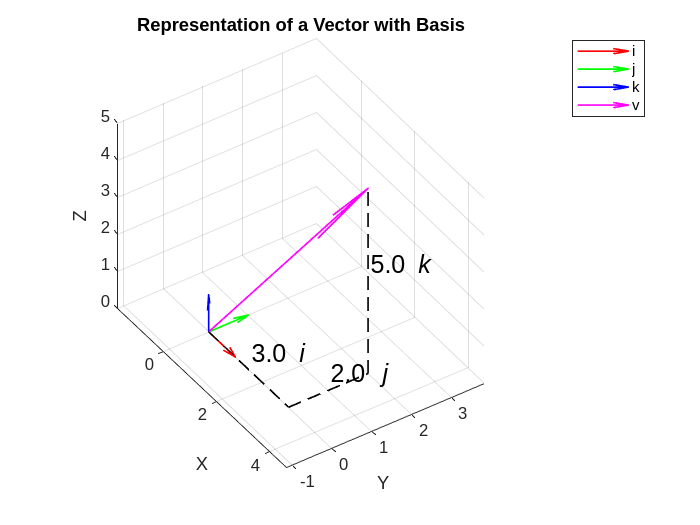

clear; close all; clc;

% Define basis vectors
i = [1; 0; 0];
j = [0; 1; 0];
k = [0; 0; 1];

% Define an arbitrary 3D vector v
v = [3; 2; 5];

% Visualization 
figure;
hold on;
grid on;
axis equal;

% Draw the basis vectors
quiver3(0, 0, 0, i(1), i(2), i(3), 'r', LineWidth=1, AutoScale='off', MaxHeadSize=1, DisplayName='i');
quiver3(0, 0, 0, j(1), j(2), j(3), 'g', LineWidth=1, AutoScale='off', MaxHeadSize=1, DisplayName='j');
quiver3(0, 0, 0, k(1), k(2), k(3), 'b', LineWidth=1, AutoScale='off', MaxHeadSize=1, DisplayName='k');

% Draw the vector v
quiver3(0, 0, 0, v(1), v(2), v(3), 'm', LineWidth=1, AutoScale='off', MaxHeadSize=1, DisplayName='v');

% Visualize each multiplication of basis vector
plot3([0 v(1)], [0 0], [0 0], 'k--', 'LineWidth', 1, HandleVisibility='off');
plot3([v(1) v(1)], [0 v(2)], [0 0], 'k--', LineWidth=1, HandleVisibility='off');
plot3([v(1) v(1)], [v(2) v(2)], [0 v(3)], 'k--', LineWidth=1, HandleVisibility='off');

% Visualize the values of multiplication
text(v(1)/2, 0, 0, sprintf('%0.1f \\iti', v(1)), 'VerticalAlignment','bottom', FontSize=15);
text(v(1), v(2)/2, 0, sprintf('%0.1f \\itj', v(2)), VerticalAlignment="bottom", FontSize=15);
text(v(1), v(2), v(3)/2, sprintf('%0.1f \\itk', v(3)), VerticalAlignment="bottom", FontSize=15);

xlabel('X');
ylabel('Y');
zlabel('Z');
title('Representation of a Vector with Basis');
% legend('i','j','k','v','Location', 'northeastoutside');
legend("show", Location="northeastoutside");

view(45, 45); % Adjust the 3D view angle
hold off;